sub = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\pp"+1+"_HRIRs_simulated.sofa");
%test = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\pp"+77+"_HRIRs_simulated.sofa");
%test = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\Subj_gen\Sub1_45.sofa");
%test = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\Oldenburg\HRIRs_SOFA\KEMAR-ECEbl.sofa")
test  = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\Subj_gen\Sub1_45v2.sofa");

test.ListenerPosition = sub.ListenerPosition

test = struct with fields:
               GLOBAL_Conventions: 'SOFA'
                   GLOBAL_Version: '1.0'
           GLOBAL_SOFAConventions: 'SimpleFreeFieldHRIR'
    GLOBAL_SOFAConventionsVersion: '1.0'
                   GLOBAL_APIName: 'ARI SOFA API for Matlab/Octave'
                GLOBAL_APIVersion: '1.0.2'
           GLOBAL_ApplicationName: 'Matlab'
        GLOBAL_ApplicationVersion: '9.2.0.538062 (R2017a)'
             GLOBAL_AuthorContact: 'florian.denk@uol.de'
                   GLOBAL_Comment: 'Microphone and loudspeaker responses compensated by spectral deconvolution. Data for frequencies below 60 Hz extrapolated. Broadband gain applied to full HRTF set, to get 0 dB in directional average for low frequencies.'
                  GLOBAL_DataType: 'FIR'
                   GLOBAL_History: 'Measured, Reflections removed using frequency dependent truncation, equalized for loudspeaker and microphone, low frequency response flattened, windowed'
                   GLOBAL_License

conf = SFS_config;
conf.N = 4096;
% load lookup table
lookup = itd2angle_lookuptable(sub);

x0 = SOFAcalculateAPV(sub);
% generate noise signal
sig_noise = noise(round(test.Data.SamplingRate/5),1,'white');
% azimuth angles
phi = -60:10:60;
phi_auditory_event = zeros(1,length(phi));
phi_sound_event = zeros(1,length(phi));

for ii=1:length(phi)
    % generate noise coming from the given direction
    ir = get_ir(test,[0 0 0],[0 0],[rad(phi(ii)) 0 x0(ii,3)], ...
                'spherical',conf);
    sig = auralize_ir(ir,sig_noise,1,conf);
    phi_auditory_event(ii) = wierstorf2013_estimateazimuth(sig,lookup,'dietz2011');
    phi_sound_event(ii) = phi(ii);
end

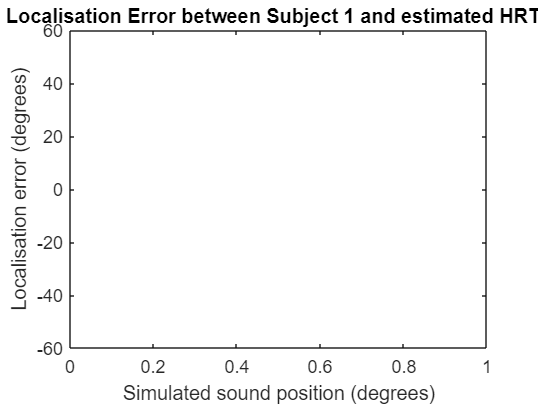

ownerr = phi_auditory_event - phi_sound_event;
RMStxt = strcat('RMS =', string(rms(ownerr)));
figure;
plot(phi_sound_event,ownerr);
title('Localisation Error between Subject 1 and estimated HRTF');
text(20,-5,RMStxt)
ylim([-60 60])
xlabel('Simulated sound position (degrees)');
ylabel('Localisation error (degrees)');

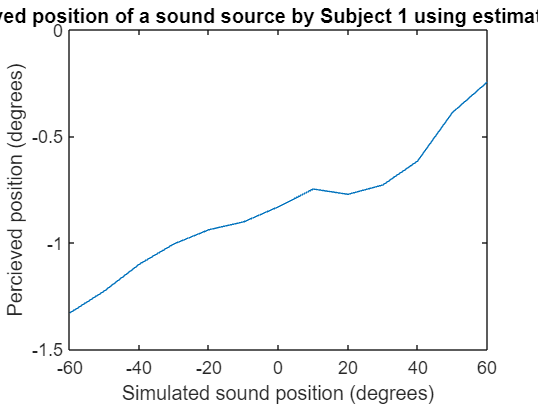

figure;
plot(phi_sound_event,phi_auditory_event);
title('Percieved position of a sound source by Subject 1 using estimated HRTF');
ylim([-1.5 0])
xlabel('Simulated sound position (degrees)');
ylabel('Percieved position (degrees)');

conf = SFS_config;
conf.N = 4096;
errerr = zeros(10,1);
for i = 1:1
    % load lookup table
    lookup = itd2angle_lookuptable(sub);
    
    x0 = SOFAcalculateAPV(sub);
    % generate noise signal
    sig_noise = noise(test.Data.SamplingRate/5,1,'white');
    % azimuth angles
    phi = -60:60;
    phi_auditory_event = zeros(1,length(phi));
    phi_sound_event = zeros(1,length(phi));
    
    for ii=1:length(phi)
        % generate noise coming from the given direction
        ir = get_ir(test,[0 0 0],[0 0],[rad(phi(ii)) 0 x0(ii,3)], ...
                    'spherical',conf);
        sig = auralize_ir(ir,sig_noise,1,conf);
        phi_auditory_event(ii) = wierstorf2013_estimateazimuth(sig,lookup,'dietz2011');
        phi_sound_event(ii) = phi(ii);
    end
    
    ownerr = phi_auditory_event - phi_sound_event;
    errerr(i) = rms(ownerr);
end
mean(errerr)

figure;
plot(phi_sound_event,ownerr);
title('Localisation Error between Subject 1 and Subject 73');
text(20,-5,'RMS = 4.94')
ylim([-10 10])
xlabel('Simulated sound position (degrees)');
ylabel('Localisation error (degrees)');

sub = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\pp"+1+"_HRIRs_simulated.sofa");
err_row = zeros(1,95)

err_row =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i=1:95
test = SOFAload("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\pp"+i+"_HRIRs_simulated.sofa");
err_row(i) = HRTF_err_comp2(sub, test)

end

err_row =     0.6332         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270         0         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335         0         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037         0         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723         0         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549         0         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702         0         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769         0         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657         0         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657    4.2253         0         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657    4.2253    3.5160         0         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657    4.2253    3.5160    1.0339         0         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657    4.2253    3.5160    1.0339    7.8827         0         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657    4.2253    3.5160    1.0339    7.8827    2.7484         0         0


err_row =     0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308    0.7482    3.7167    3.7378    5.7365    1.6662   10.8270    4.9335    4.2037    5.8723    4.2549    7.3702    5.9769    7.7657    4.2253    3.5160    1.0339    7.8827    2.7484    3.8558         0


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308


err_row = 1×95
    0.6332    2.6841    5.7551    1.8162    8.1288    2.5625    3.6995    5.6921    3.6051    6.4324    3.9154    3.3316    3.9083    1.7113    5.1774    5.2119    5.4613    5.8702    2.3434    5.8747    5.4822    2.4427    4.6819    3.5630    8.6362    4.3200    1.5643    4.1094    4.5119    2.0308
